# Project 2

*Authors:* Dakota Chang and Kenneth Xiong

*Last Updated: *November 4, 2023

*Summary: *This computational essay serves as the ModSim 23-24 Fall Term Project 2, focusing on the modeling query: 'How does class size influence disease spread within a student population?' Employing an agent-based model and a complete graph featuring pods of various sizes and weights, we aim to address this question. The notebook is structured into four main sections: Question, Methodology, Results, and Interpretation.

## Question: How does class size influence disease spread within a student population?

### Background Information + References:

Since the COVID-19 pandemic, schools have been interested in studying the nature of disease transmission in their classrooms. Schools were beginning to open their doors to in-person learning and needed to understand how that would affect the transmission of COVID-19 (Hekmati). They found that there was very little research on the behavior of infectious diseases and what preventive measures would be most effective(COVID-19 Working Group). When there was information about disease transmission, it was based on assumptions(like how class size affects transmission) that might have led to biased results(COVID-19 Working Group). Because of this, this essay seeks to explain how different class sizes affect disease spread within a given population.Not only is understanding this important for preventing future pandemics, but it’s also important for stemming the spread of other diseases that thrive in school environments like influenza(Endo et al.).

Research Synthesis Matrix: [https://docs.google.com/spreadsheets/d/1kzDWpNepGnaOVogJqf5ZUqgpej4O49TwtW78Yk4wx2U/edit?usp=sharing](https://docs.google.com/spreadsheets/d/1kzDWpNepGnaOVogJqf5ZUqgpej4O49TwtW78Yk4wx2U/edit?usp=sharing)

## METHODOLOGY

**Model:**

We used the same SIR agent based model as worksheep four. To best capture the dynamics of the social network within a school, we've opted for a "leaky pod" agent-based model. In this model, each pod corresponds to a specific class. The strength of connections between individual agents within a pod is determined by class size, with smaller classes resulting in more robust connections. We've chosen to represent this relationship using a ratio of class size/total populaition. 

Additionally, our model is designed as a complete graph to simulate the comprehensive interconnections characteristic of a school's social network. However, it's important to note that these connections are intentionally configured to be relatively weak in nature.

**Assumptions:**

We hypothesize that smaller class sizes foster stronger connections among students within a particular class. This hypothesis is grounded in the observation that larger classes typically adopt a lecture-based format in extensive lecture halls, whereas smaller classes often emphasize interactive and team-based learning. These assumptions are reasonable within the context of our model, which investigates the impact of class sizes and teaching styles on disease transmission. 

We also assume complete interconnectedness among all students might not hold true in larger colleges. Moreover, we've assumed equal connectivity among students within each class. Nevertheless, these specific assumptions might not be directly pertinent to our primary modeling objective, which primarily focuses on the effects of class size and teaching methodologies on disease spread rather than providing a precise estimation of disease transmission rates.

We also assume that class sizes are the same for all classes. While this might be accurate for smaller institutions, this does not hold for larger institutions where large lecture-format classes only account for a small percent of the total classes. We feel that the impact of this assumption varies based on year of college students are in. Freshman might have only large classes, while senior won't have any.

Here is the code to conduct three distinct simulations across 150 time steps. One simulation focuses on small class sizes, assuming 10 students per class. The second simulation involves medium class sizes, with an assumed count of 50 students per class. The third simulation pertains to large class sizes, where an assumed count of 100 students per class is utilized. The total school population is set at 1000 individuals. As previously highlighted, these assumptions are designed not to significantly impact the ultimate results, as our primary aim is to observe trends rather than precisely predict disease spread rates.

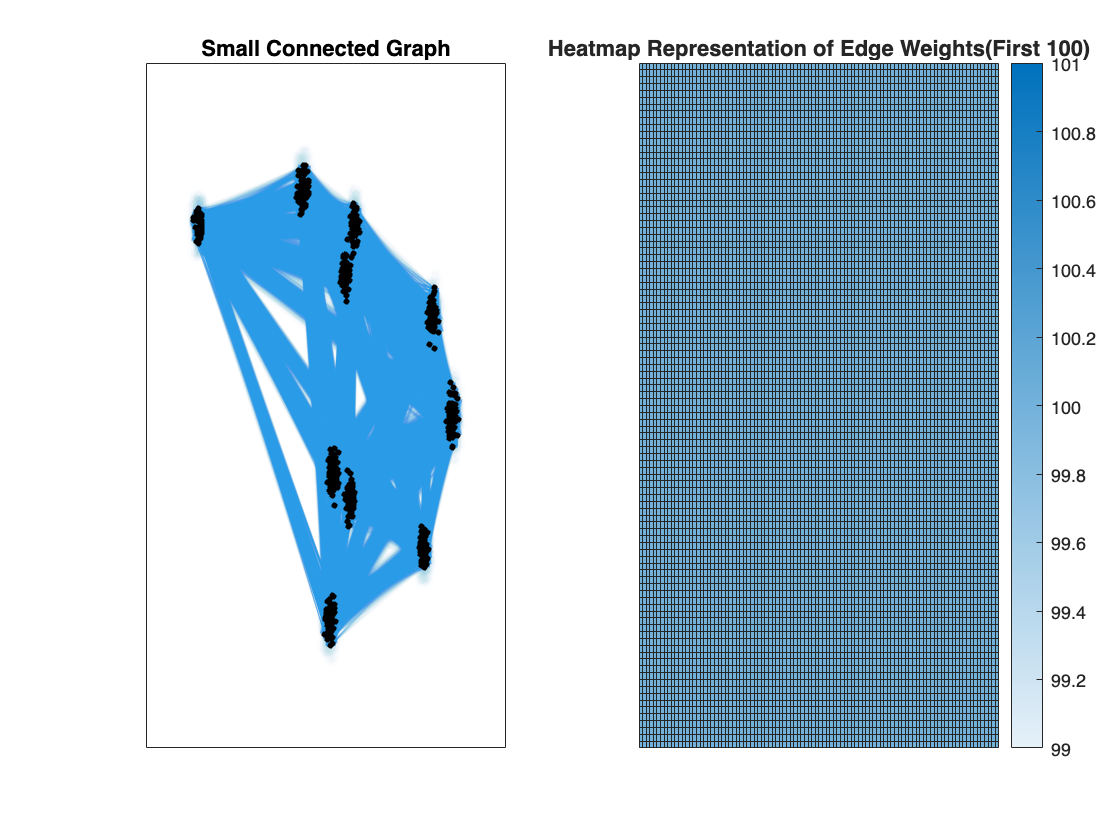

total_pop = 1000;

% creates complete graph overlaid by leaky pod graph to calibrate connection weights 
[M_small, plot_small] = create_classes(total_pop , 100, total_pop /10, "Small Connected Graph"); % small class

*Figure 1: Graph and heatmap for small classes*

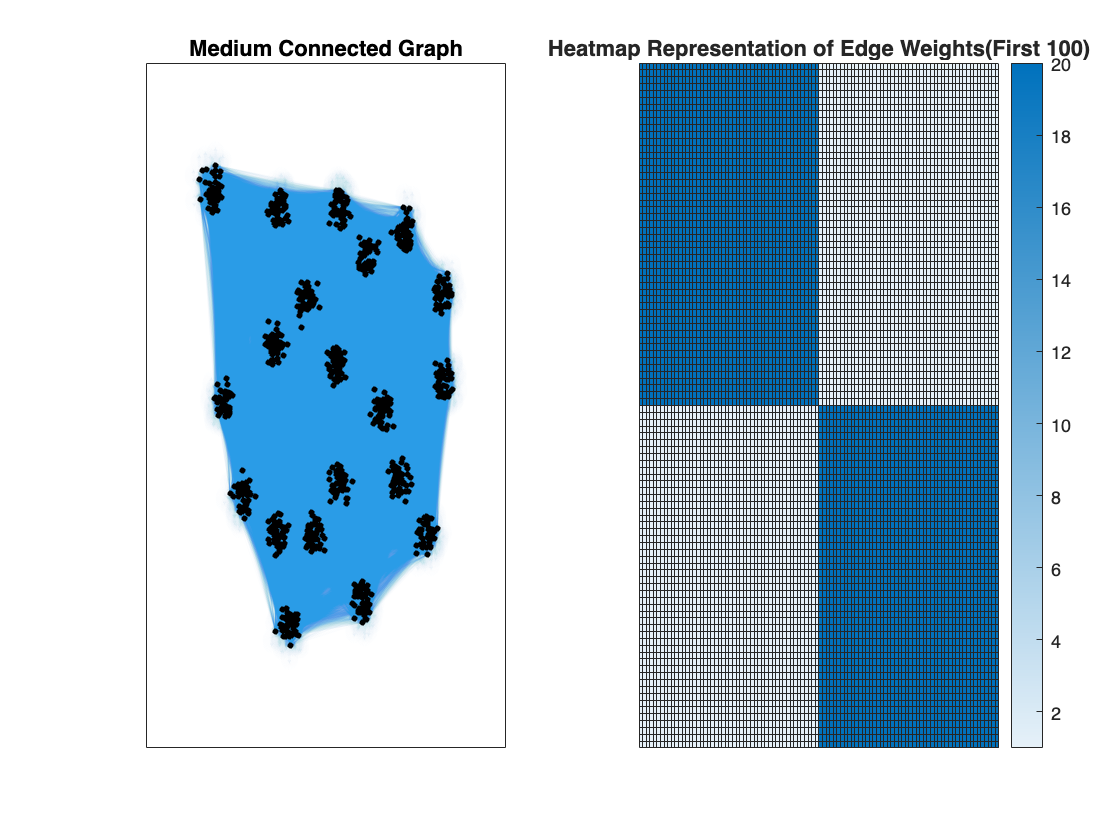

[M_medium, plot_medium] = create_classes(total_pop , 50, total_pop /50, "Medium Connected Graph"); % medium class

*Figure 2: Graph and heatmap for medium classes*

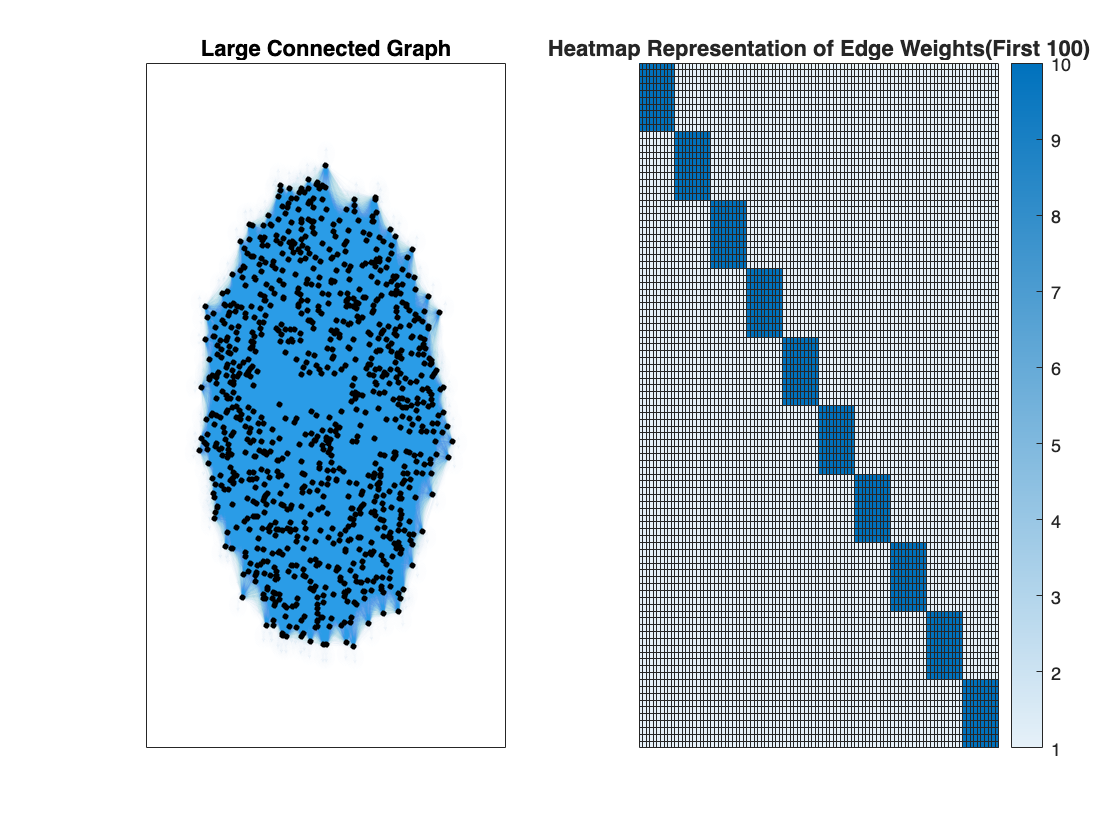

[M_big, plot_big] = create_classes(total_pop , 10, total_pop /100, "Large Connected Graph"); % big class

*Figure 3: Graph and heatmap for large classes*

% matrix of same size to store infected persons per time step,
% matrix starts with one as we assume one student to be patient #0.
Iv1 = zeros(total_pop , 1);
Iv1(1) = 1;

% infection and recovery rate
infection_rate = 0.003; recovery_rate = 0.1;

% Set the number of replications for the agent-based model
n_realizations = 100;

%time to run
T_simulation = 150;

% Reserve space for simulation results
Is_ensemble = zeros(T_simulation, n_realizations);
Im_ensemble = zeros(T_simulation, n_realizations);
Ib_ensemble = zeros(T_simulation, n_realizations);
%Space for maxes
Is_max = zeros(1, n_realizations);
Im_max = zeros(1, n_realizations);
Ib_max = zeros(1, n_realizations);


% Set the random seed. This is something we'll talk about in the next
% module.
rng(101)

% simulation of disease spread in constructed models
for i = 1 : n_realizations
    [Ss, Is, Rs] = simulate_absir(M_small, Iv1, T_simulation, infection_rate, recovery_rate);
    [Sm, Im, Rm] = simulate_absir(M_medium, Iv1, T_simulation, infection_rate, recovery_rate);
    [Sb, Ib, Rb] = simulate_absir(M_big, Iv1, T_simulation, infection_rate, recovery_rate);
    Is_ensemble(:, i) = sum(Is, 1);
    Im_ensemble(:, i) = sum(Im, 1);
    Ib_ensemble(:, i) = sum(Ib, 1);
    Is_max(i) = max(sum(Is, 1));
    Im_max(i) = max(sum(Im, 1));
    Ib_max(i) = max(sum(Ib, 1));
end
%calc the mean
Is_mean = mean(Is_ensemble, 2);
Im_mean = mean(Im_ensemble, 2);
Ib_mean = mean(Ib_ensemble, 2);


%verification facts
%make sure agent is only in one state at a time
assert(sum(all(Ss+Is+Rs==1))==150)
%make sure an agent isn't in a fracitonal state(checking if rounding down
%in the matrix creates a matrix than is different from the original
assert(sum(all(floor(Ss) ~= Ss,'all')) == 0)
assert(sum(all(floor(Rs) ~= Rs,'all')) == 0)
assert(sum(all(floor(Is) ~= Is,'all')) == 0)

%make sure agent is only in one state at a time
assert(sum(all(Ss+Is+Rs==1))==150)
%make sure an agent isn't in a fracitonal state(checking if rounding down
%in the matrix creates a matrix than is different from the original
assert(sum(all(floor(Sm) ~= Sm,'all')) == 0)
assert(sum(all(floor(Rm) ~= Rm,'all')) == 0)
assert(sum(all(floor(Im) ~= Im,'all')) == 0)

%make sure agent is only in one state at a time
assert(sum(all(Ss+Is+Rs==1))==150)
%make sure an agent isn't in a fracitonal state(checking if rounding down
%in the matrix creates a matrix than is different from the original
assert(sum(all(floor(Sb) ~= Sb,'all')) == 0)
assert(sum(all(floor(Rb) ~= Rb,'all')) == 0)
assert(sum(all(floor(Ib) ~= Ib,'all')) == 0)


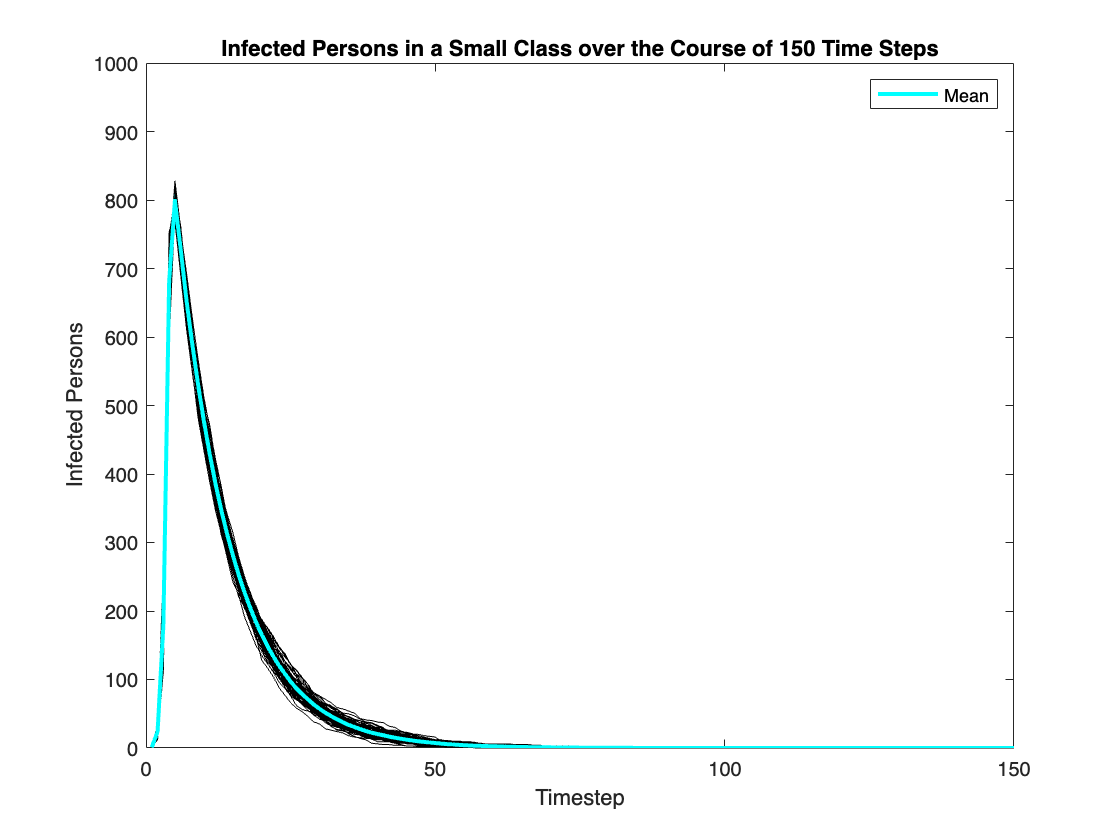

% Visualize
figure()
plot(Is_ensemble, 'k-', 'LineWidth', 0.1, 'HandleVisibility', 'off'); hold on;
plot(Is_mean, 'c-', 'LineWidth', 2.0, 'DisplayName', 'Mean');
xlabel('Timestep')
ylabel('Infected Persons')
ylim([0 1000])
legend()
legend()
title("Infected Persons in a Small Class over the Course of 150 Time Steps")
xlabel('Timestep')
ylabel('Infected Persons')

Figure 4: Mean infection graph for small class

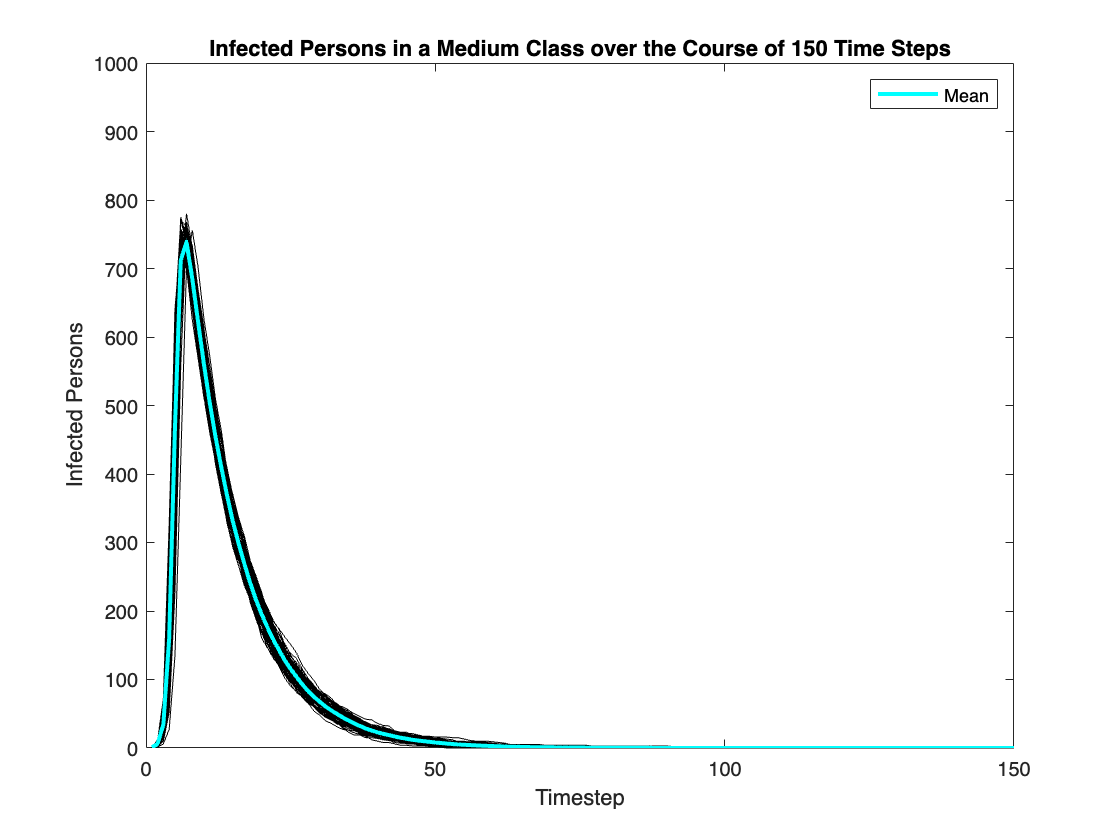

clf;
figure()
plot(Im_ensemble, 'k-', 'LineWidth', 0.1, 'HandleVisibility', 'off'); hold on;
plot(Im_mean, 'c-', 'LineWidth', 2.0, 'DisplayName', 'Mean');
xlabel('Timestep')
ylabel('Infected Persons')
ylim([0 1000])
legend()
legend()
title("Infected Persons in a Medium Class over the Course of 150 Time Steps")
xlabel('Timestep')
ylabel('Infected Persons')

Figure 5: Mean infection graph for medium class

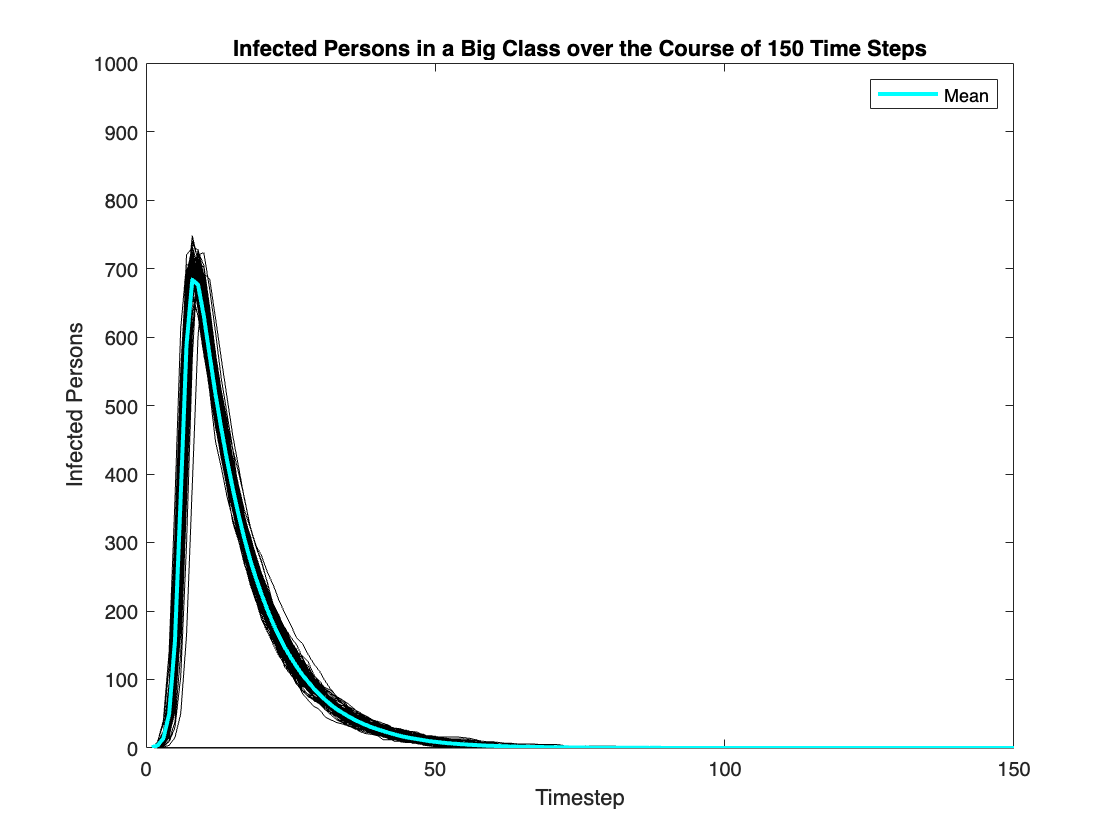


clf;
figure()
plot(Ib_ensemble, 'k-', 'LineWidth', 0.1, 'HandleVisibility', 'off'); hold on;
plot(Ib_mean, 'c-', 'LineWidth', 2.0, 'DisplayName', 'Mean');
xlabel('Timestep')
ylabel('Infected Persons')
ylim([0 1000])
legend()
legend()
title("Infected Persons in a Big Class over the Course of 150 Time Steps")
xlabel('Timestep')
ylabel('Infected Persons')

Figure 6: Mean infection graph for large class

## Parameter Sweep For Different Class Sizes

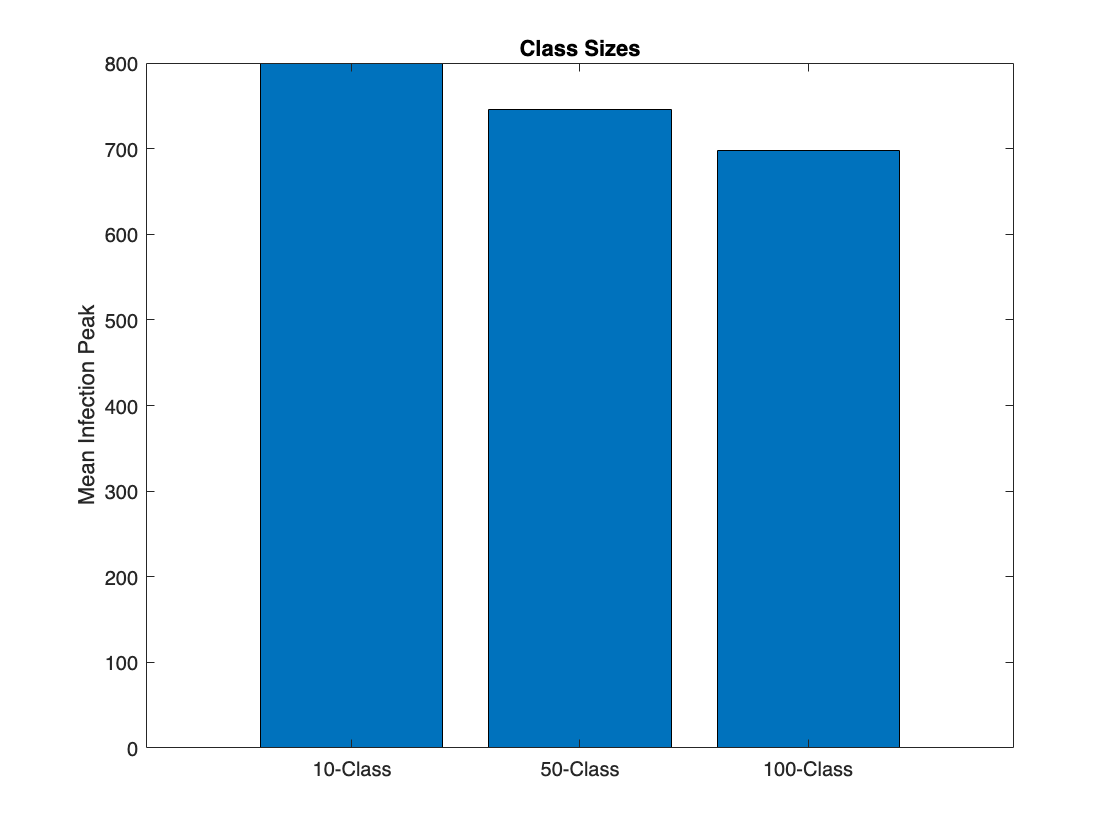

I_max_data = [
    Is_max;
    Im_max;
    Ib_max
];
X = categorical({'10-Class', '50-Class', '100-Class'});
X = reordercats(X, {'10-Class', '50-Class', '100-Class'});

figure(); clf;
bar(X, mean(I_max_data, 2))
ylabel('Mean Infection Peak')
title('Class Sizes')

Figure 7: Parameter sweep based on class size

## Parameter Sweep (Infection Rate)

% parameter sweep for infection rate:
infection_rate = 0:0.0001:0.01;
recovery_rate = 0.1;
n_realizations = 10;
Is_peak = zeros(1, n_realizations); Im_peak = zeros(1, n_realizations); Ib_peak = zeros(1, n_realizations);
Is_peak_mean = zeros(1, 100); Im_peak_mean = zeros(1, 100); Ib_peak_mean= zeros(1, 100);

for i = 1 : length(infection_rate)
    for j = 1 : n_realizations
        [Ss, Is, Rs] = simulate_absir(M_small, Iv1, length(infection_rate), infection_rate(i), recovery_rate);
        [Sm, Im, Rm] = simulate_absir(M_medium, Iv1, length(infection_rate), infection_rate(i), recovery_rate);
        [Sb, Ib, Rb] = simulate_absir(M_big, Iv1, length(infection_rate), infection_rate(i), recovery_rate);

        Is_peak(j) = max(sum(Is, 1)); 
        Im_peak(j) = max(sum(Im, 1));
        Ib_peak(j) = max(sum(Ib, 1));
    end
    Is_peak_mean(i) = mean(Is_peak);
    Im_peak_mean(i) = mean(Im_peak);
    Ib_peak_mean(i) = mean(Ib_peak);
end

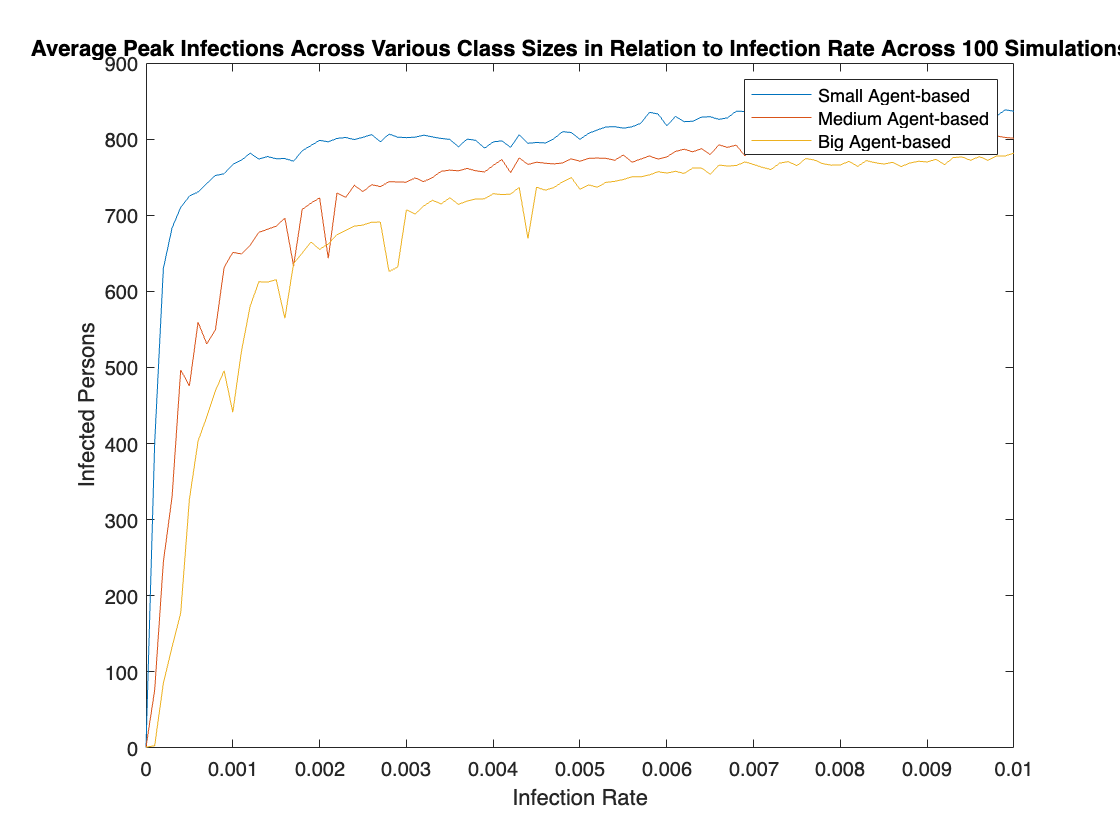

clf;
figure()
plot(0:0.0001:0.01,Is_peak_mean, 'DisplayName', 'Small Agent-based'); hold on;
plot(0:0.0001:0.01,Im_peak_mean, 'DisplayName', 'Medium Agent-based');
plot(0:0.0001:0.01,Ib_peak_mean, 'DisplayName', 'Big Agent-based');
legend()
title("Average Peak Infections Across Various Class Sizes in Relation to Infection Rate Across 100 Simulations")
xlabel('Infection Rate')
ylabel('Infected Persons')

Figure 8: Parameter sweep based on infection rate

## Parameter Sweep (Recovery Rate)

% parameter sweep for recovery rate:
infection_rate = 0.001;
recovery_rate = 0:0.01:1;
n_realizations = 10;
Is_peak = zeros(1, n_realizations); Im_peak = zeros(1, n_realizations); Ib_peak = zeros(1, n_realizations);
Is_peak_mean = zeros(1, 100); Im_peak_mean = zeros(1, 100); Ib_peak_mean= zeros(1, 100);

for i = 1 : length(recovery_rate)
    for j = 1 : n_realizations
        [Ss, Is, Rs] = simulate_absir(M_small, Iv1, length(recovery_rate), infection_rate, recovery_rate(i));
        [Sm, Im, Rm] = simulate_absir(M_medium, Iv1, length(recovery_rate), infection_rate, recovery_rate(i));
        [Sb, Ib, Rb] = simulate_absir(M_big, Iv1, length(recovery_rate), infection_rate, recovery_rate(i));

        Is_peak(j) = max(sum(Is, 1)); 
        Im_peak(j) = max(sum(Im, 1));
        Ib_peak(j) = max(sum(Ib, 1));
    end
    Is_peak_mean(i) = mean(Is_peak);
    Im_peak_mean(i) = mean(Im_peak);
    Ib_peak_mean(i) = mean(Ib_peak);
end

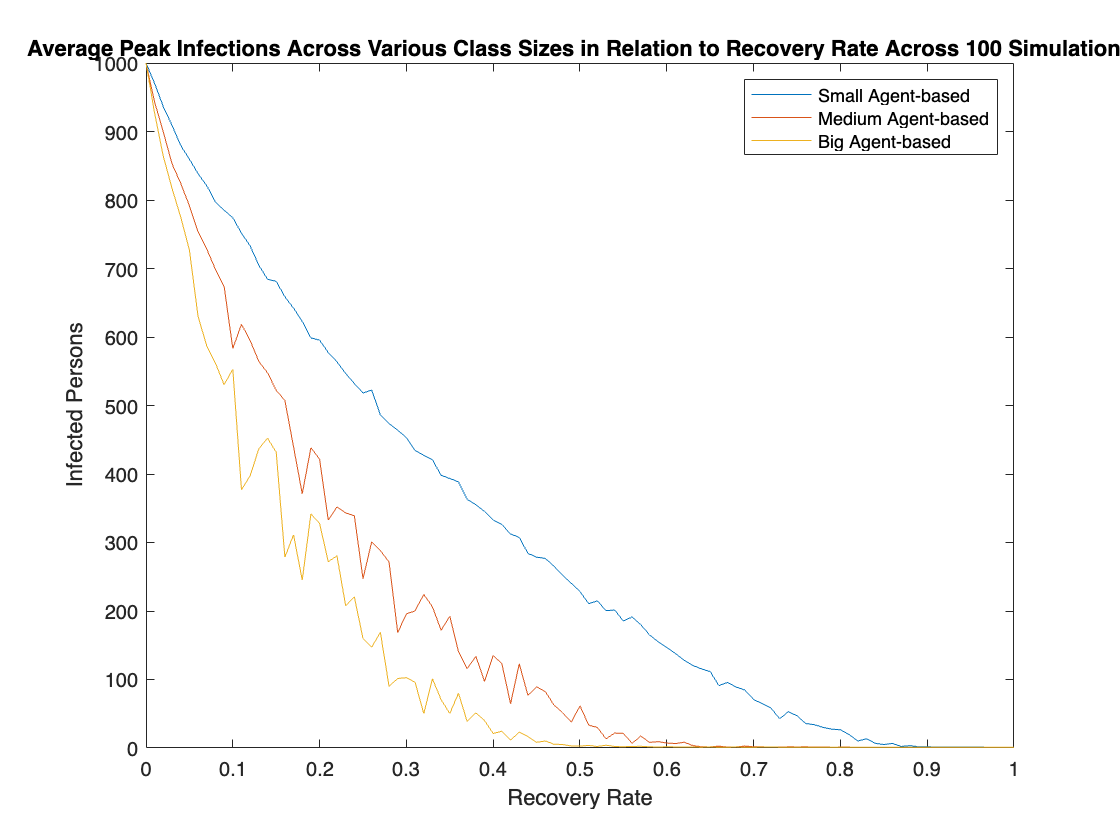

clf;
figure()
plot(0:0.01:1,Is_peak_mean, 'DisplayName', 'Small Agent-based'); hold on;
plot(0:0.01:1,Im_peak_mean, 'DisplayName', 'Medium Agent-based');
plot(0:0.01:1,Ib_peak_mean, 'DisplayName', 'Big Agent-based');
legend()
title("Average Peak Infections Across Various Class Sizes in Relation to Recovery Rate Across 100 Simulations")
xlabel('Recovery Rate')
ylabel('Infected Persons')

Figure 9: Parameter sweep based on recovery rate

### Development:

Verification Facts: To verify that our model is correct, we checked two things: each agent isn’t in more than one state(i.e the value is greater than one), and agents aren’t in multiple fractional states. If both of these are true, then our model should be correct.

## Results

## Metrics and Sweeps:

We performed a parameter sweep(fig. 7) across the different sizes of classes with the metric of mean infection peak. We felt that this was a good metric because it accurately represents the extent of infection spread across our population. It also accounts for the randomness of each realization by relying on the mean which is based on all realizations.

We also performed parameter sweeps(fig. 8,9) for infection and recovery rate for all three class sizes. We used the same metric of mean peak infection for these as well. One thing to note is that these means are calculated over only ten realizations instead of 100. 100 realizations was too computationally streneous for matlab to handle, so we had to settle with 10.

### Analysis:

The result of our parameter sweeps is that the smaller classes have the highest peak infections, followed by medium classes and large classes. From our parameters sweeps for infection rate and recovery rate, we see that this is true for all values of infection and recovery that don't result in unrealistically rapid infection or recovery.

### Validation:

There is tangential evidence to support out results. *Within and between classroom transmission patterns of seasonal influenza among primary school students in Matsumoto city, Japan *details a similar trend with class sizes. Their study of classes of  20, 30, 40 students found that there was no significant difference. However, our values for small and medium classes are within the error that they set for their study.

Furthermore, *Simulating COVID-19 In a University Environment, *which studied prevention techniques found that moving large classes online was extremely effective at reducing COVID-19 infections. This matches are simulation data in the sense that large classes still result in a large amount of infections, so it is effective to move them online because one class represents a much larger precentage of the population compared to moving a medium or small class online.

## Interpretation

### Therefore:

From our results and parameters sweeps, we find that smaller class sizes tend to result in the most disease spread as compared to medium or large classes.

### Limitations and Future Work:

Modeling all the intricacies of a school is really difficult. There are a lot of different parameters that go into creating an accurate representation of a school like varying class sizes, social circles, teachers, and dorm buildings all of which we did not include in our model. For the sake of this project, we only looked at uniform classes with a very oversimplified representation of social bonds. Because of this, this model is probably most accurate at representing small to medium classes that would be held at small schools where our assumptions about social interconnectedness and classes are true. However, with larger classes and therefore larger schools, these assumptions begin to cause our model to detach itself from reality. 

Future work for this model would definitely start with implementing any of the assumptions/complications to this model that we listed above. Additionally, results from running more realizations for our parameter sweeps would be another avenue that we could explore. Ten realizations really is not enough data to be able to make any meaningful assumptions from.